assert(endsWith(pwd, "ferromagnetic metal disk in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)
Coil.z            = 5.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)

#### Sensor

Sensor.num = 20;
Sensor.side_length = 0.4e-3;

Sensor.position = [linspace(6e-3,30e-3,Sensor.num); 2.5e-3*ones(1,Sensor.num)];

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 30; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.02 seconds


clear disk r z

Model.conductivity = 1.45e6 * ones(1,Model.num_elms); % (S/m)
Model.relative_permeability = 50 * ones(1,Model.num_elms); % (1)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, Coil, Sensor);

build governing equation took 105.74 seconds


#### Solve in frequency domain

Coil.frequency_domain.voltage = 1; % (V)
% Coil.frequency_domain = rmfield(Coil.frequency_domain, 'voltage');
% Coil.frequency_domain.current = 2.8347 - 0.9188i; % (A)

Coil.frequency_domain.frequency = 500; % (Hz)

[Model, Coil, Sensor] = SolveFrequencyDomain2D(GoverningEquation, Model, Coil, Sensor);

solve in frequency domain took 0.04 seconds


#### Plot result

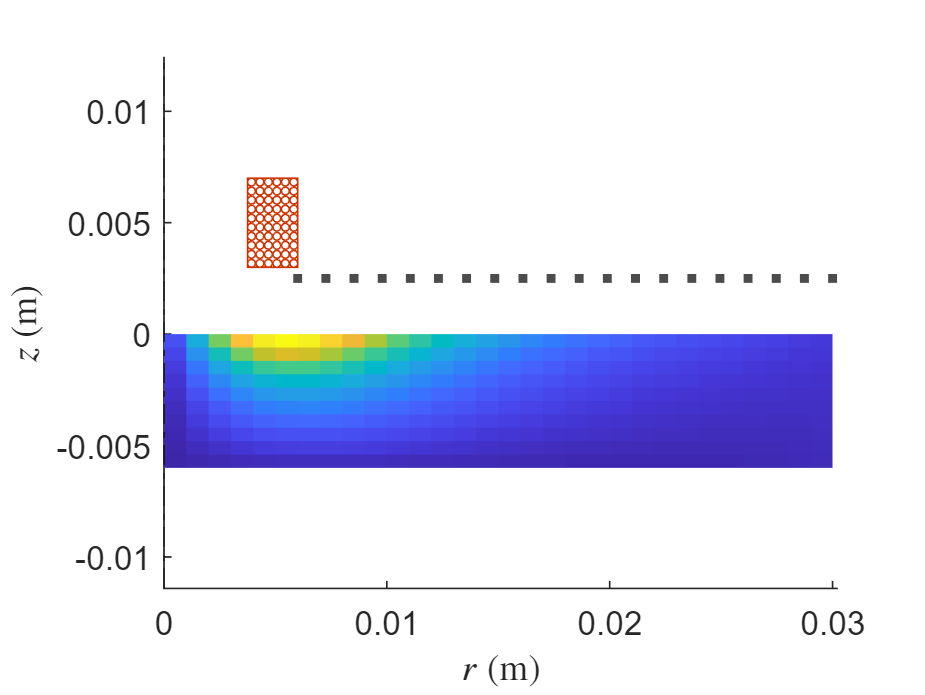

PlotWorld2D(Model, Coil, Sensor, abs(Model.frequency_domain.J));

clf

## Compare with FEA

#### Current density

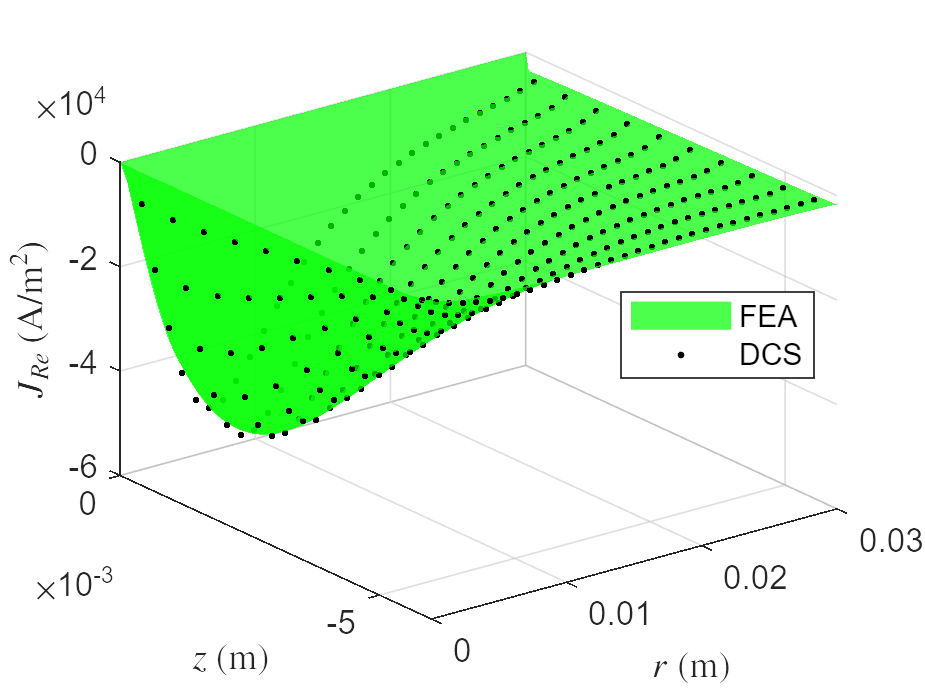

data = readmatrix('FEA_data/J.txt', 'CommentStyle','%');
FEA.r = reshape(data(:,1), 100, []);
FEA.z = reshape(data(:,2), 100, []);
FEA.J = reshape(data(:,3), 100, []);
clear data

surf(FEA.r,FEA.z, real(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), real(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Re}$ (A/m$^2$)", 'Interpreter','latex')
hold off

clf

J_FEA = interp2(FEA.r', FEA.z', real(FEA.J)', Model.elms_center(1,:), Model.elms_center(2,:));
J_DSC = real(Model.frequency_domain.J);
relative_error = mean(abs((J_DSC - J_FEA) ./ J_FEA));
fprintf("average relative error: %f", relative_error)

average relative error: 0.015621

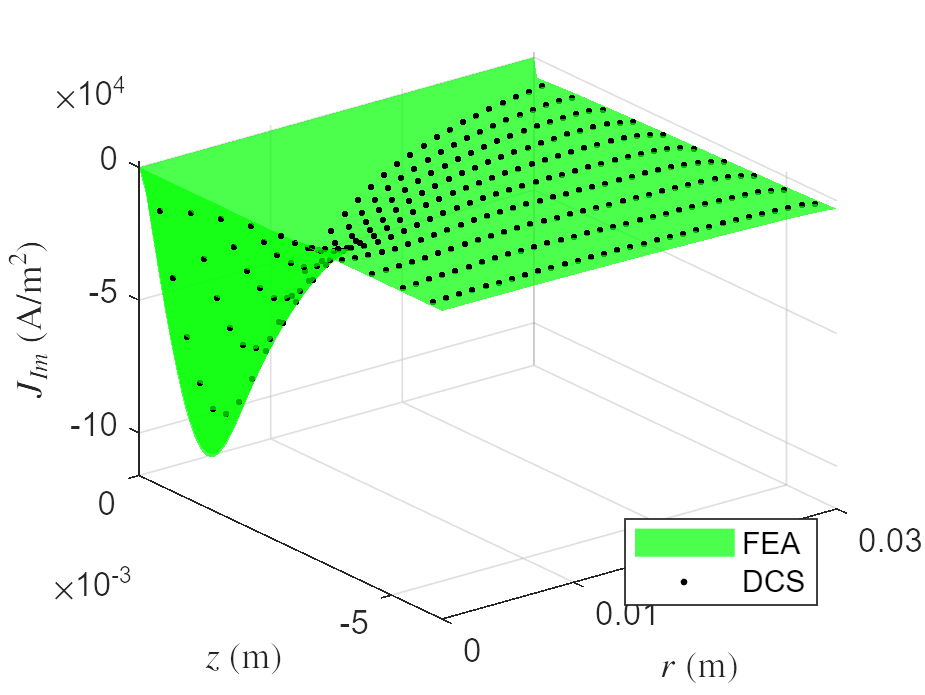


surf(FEA.r,FEA.z, imag(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), imag(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Im}$ (A/m$^2$)", 'Interpreter','latex')
hold off

clf

J_FEA = interp2(FEA.r', FEA.z', imag(FEA.J)', Model.elms_center(1,:), Model.elms_center(2,:));
J_DSC = imag(Model.frequency_domain.J);
relative_error = mean(abs((J_DSC - J_FEA) ./ J_FEA));
fprintf("average relative error: %f", relative_error)

average relative error: 0.441108


clear J_FEA J_DSC relative_error

#### Magnetic flux density

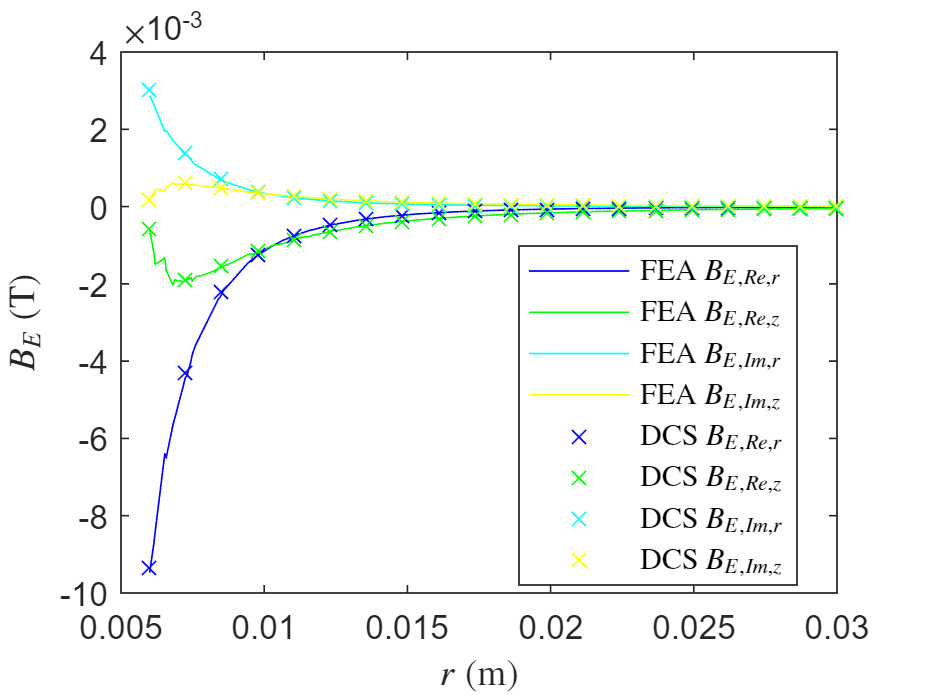

data = readmatrix('FEA_data/B_E.txt', 'CommentStyle','%');
FEA.r_sensor = data(:,1);
FEA.B_E_r = data(:,3);
FEA.B_E_z = data(:,4);
data = readmatrix('FEA_data/B.txt', 'CommentStyle','%');
FEA.B_C_r = data(:,3) - FEA.B_E_r;
FEA.B_C_z = data(:,4) - FEA.B_E_z;
clear data

plot(FEA.r_sensor, real(FEA.B_E_r), 'b-', 'DisplayName','FEA $B_{E,Re,r}$'); hold on
plot(FEA.r_sensor, real(FEA.B_E_z), 'g-', 'DisplayName','FEA $B_{E,Re,z}$');
plot(FEA.r_sensor, imag(FEA.B_E_r), 'c-', 'DisplayName','FEA $B_{E,Im,r}$');
plot(FEA.r_sensor, imag(FEA.B_E_z), 'y-', 'DisplayName','FEA $B_{E,Im,z}$');
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(1,:)), 'bx', 'DisplayName','DCS $B_{E,Re,r}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(2,:)), 'gx' ,'DisplayName','DCS $B_{E,Re,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_E(1,:)), 'cx', 'DisplayName','DCS $B_{E,Im,r}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_E(2,:)), 'yx' ,'DisplayName','DCS $B_{E,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

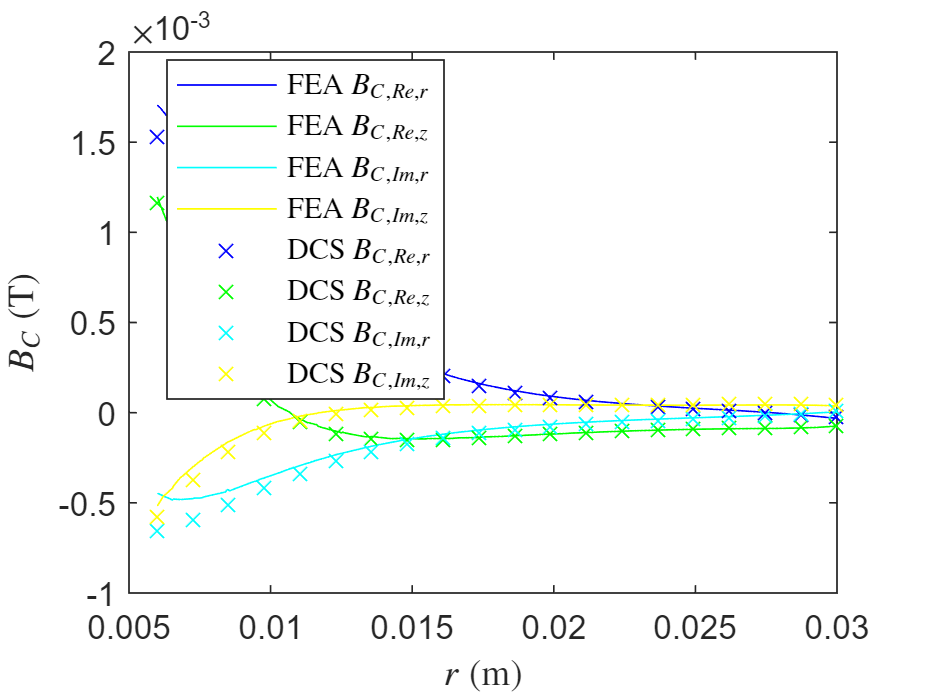

clf

plot(FEA.r_sensor, real(FEA.B_C_r), 'b-', 'DisplayName','FEA $B_{C,Re,r}$'); hold on
plot(FEA.r_sensor, real(FEA.B_C_z), 'g-', 'DisplayName','FEA $B_{C,Re,z}$');
plot(FEA.r_sensor, imag(FEA.B_C_r), 'c-', 'DisplayName','FEA $B_{C,Im,r}$');
plot(FEA.r_sensor, imag(FEA.B_C_z), 'y-', 'DisplayName','FEA $B_{C,Im,z}$');
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Re,r}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Re,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(1,:)), 'cx', 'DisplayName','DCS $B_{C,Im,r}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(2,:)), 'yx' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf